## Lab 2.5

(a)

题目要求：将三个输入信号经过三个系统的响应及经过一定运算的结果存入向量中并绘制图像。

clear,clc
% 输入三个信号
xn = 0:5;
x1 = [1 zeros(1,5)];
x2 = [0 1 zeros(1,4)];
x3 = [1 2 zeros(1,4)];

%系统1
h = [1 -1 -1];
w1 = filter(h,1,x1)

w1 =      1    -1    -1     0     0     0


w2 = filter(h,1,x2)

w2 =      0     1    -1    -1     0     0


w3 = filter(h,1,x3)

w3 =      1     1    -3    -2     0     0


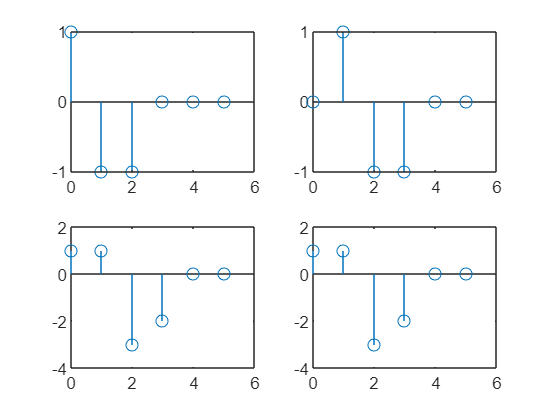

figure
subplot(2,2,1),stem(xn,w1)
subplot(2,2,2),stem(xn,w2)
subplot(2,2,3),stem(xn,w3)
subplot(2,2,4),stem(xn,w1+2.*w2)


%系统2
y1 = cos(x1)

y1 =     0.5403    1.0000    1.0000    1.0000    1.0000    1.0000


y2 = cos(x2)

y2 =     1.0000    0.5403    1.0000    1.0000    1.0000    1.0000


y3 = cos(x3)

y3 =     0.5403   -0.4161    1.0000    1.0000    1.0000    1.0000


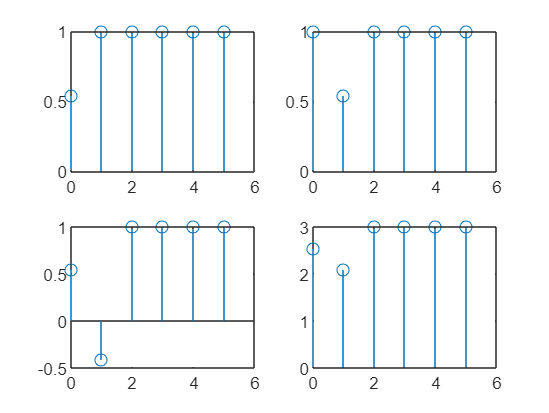

figure
subplot(2,2,1),stem(xn,y1)
subplot(2,2,2),stem(xn,y2)
subplot(2,2,3),stem(xn,y3)
subplot(2,2,4),stem(xn,y1+2.*y2)


%系统3
z1 = xn.*x1

z1 =      0     0     0     0     0     0


z2 = xn.*x2

z2 =      0     1     0     0     0     0


z3 = xn.*x3

z3 =      0     2     0     0     0     0


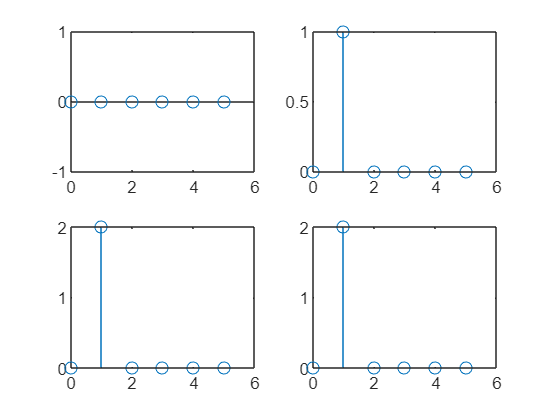

figure
subplot(2,2,1),stem(xn,z1)
subplot(2,2,2),stem(xn,z2)
subplot(2,2,3),stem(xn,z3)
subplot(2,2,4),stem(xn,z1+2.*z2)

(b)

题目要求：陈述是否每个系统都是线性的，并给出理由或者反例。

**分析：**

系统1是线性的，因为此系统满足可加性与数乘性，即

T：x[n] → x[n] - x[n-1] - x[n-2]

w1 = T(x1); w2 = T(x2); 

w3 = Aw1 + Bw2 = AT(x1) + BT(x2) = T(Ax1) + T(Bx2) = T(Ax1 + Bx2).

系统2不是线性的，由系统2生成的图组可以看出，'y1+2.*y2'作出的图形与'y3'做出的图形并不相同。

系统3是线性的，因为此系统满足可加性与数乘性，即

T：x[n] → nx[n]

w1 = T(x1); w2 = T(x2); 

w3 = Aw1 + Bw2 = AT(x1) + BT(x2) = T(Ax1) + T(Bx2) = T(Ax1 + Bx2).

**结论：**

系统1、3是线性的，系统2是非线性的。

(c)

题目要求：陈述是否每个系统都是时不变的，并给出理由或者反例。

**分析：**

系统1是时不变的，因为

x[n] → w[n] = x[n] - x[n-1] - x[n-2]

x'[n] = x[n-n0] → w'[n] = x[n-n0] - x[n-n0-1] - x[n-n0-2] = w[n-n0].

系统2是时不变的，因为

x[n] → y[n] = cos(x[n])

x'[n] = x[n-n0] →  y'[n] = cos(x[n-n0]) = y[n-n0].

系统3不是时不变的，因为

x[n] → z[n] = nx[n]

x'[n] = x[n-n0] →  z'[n] = nx[n-n0] != z[n-n0].

**结论：**

系统1、2是时不变的，系统3是时变的。

(d)

题目要求：在区间[0, 19] 内计算两个系统对单位冲激函数的响应并绘制图像。

xn = 0:19;
x = [1 zeros(1,19)];
% y1
h1 = filter(1,[1 -0.6],x)

h1 =     1.0000    0.6000    0.3600    0.2160    0.1296    0.0778    0.0467    0.0280    0.0168    0.0101    0.0060    0.0036    0.0022    0.0013    0.0008    0.0005    0.0003    0.0002    0.0001    0.0001


对于系统2，我们利用解析求得h2：

y[0] = 1;

y[n] = (0.6)^(n(n+1)/2);

% y2
h2 = power(0.6,xn.*(xn+1)./2)

h2 =     1.0000    0.6000    0.2160    0.0467    0.0060    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


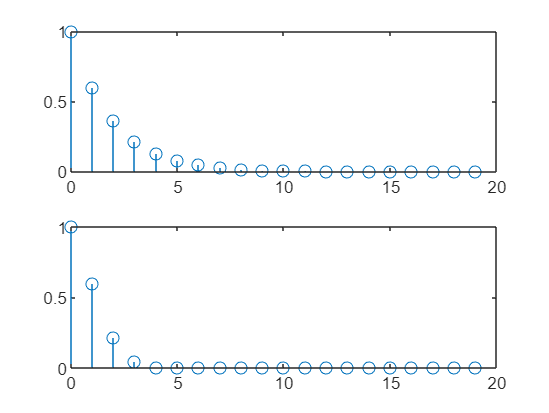

% 绘制图像
figure
subplot(2,1,1),stem(xn,h1)
subplot(2,1,2),stem(xn,h2)

**结论：**如答图。

(e)

题目要求：在区间[0, 19] 内计算两个系统对单位阶跃函数的响应并绘制图像。

u = ones(1,20);
% y1
s1 = filter(1,[1 -0.6],u)

s1 =     1.0000    1.6000    1.9600    2.1760    2.3056    2.3834    2.4300    2.4580    2.4748    2.4849    2.4909    2.4946    2.4967    2.4980    2.4988    2.4993    2.4996    2.4997    2.4998    2.4999


% y2
s2 = u;
for i = 2:20
    s2(i) = 0.6^(i) * s2(i-1) + s2(i);
end
s2

s2 =     1.0000    1.3600    1.2938    1.1677    1.0908    1.0509    1.0294    1.0173    1.0103    1.0061    1.0037    1.0022    1.0013    1.0008    1.0005    1.0003    1.0002    1.0001    1.0001    1.0000


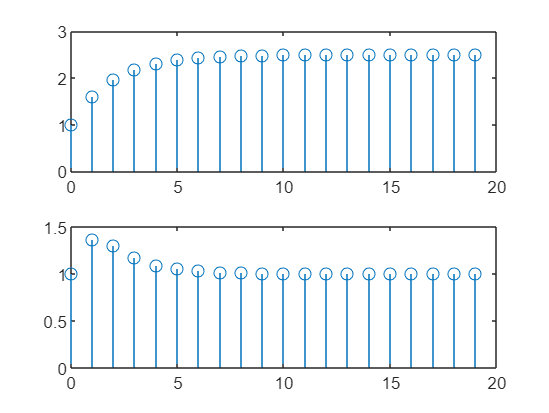

% 绘制图像
figure
subplot(2,1,1),stem(xn,s1)
subplot(2,1,2),stem(xn,s2)

**结论：**如答图。

(f)

题目要求：分别计算两个系统的h[n]与单位阶跃函数的卷积和并绘制图像。

z1 = conv(h1,u);
z1 = z1(:,1:20)

z1 =     1.0000    1.6000    1.9600    2.1760    2.3056    2.3834    2.4300    2.4580    2.4748    2.4849    2.4909    2.4946    2.4967    2.4980    2.4988    2.4993    2.4996    2.4997    2.4998    2.4999


z2 = conv(h2,u);
z2 = z2(:,1:20)

z2 =     1.0000    1.6000    1.8160    1.8627    1.8687    1.8692    1.8692    1.8692    1.8692    1.8692    1.8692    1.8692    1.8692    1.8692    1.8692    1.8692    1.8692    1.8692    1.8692    1.8692


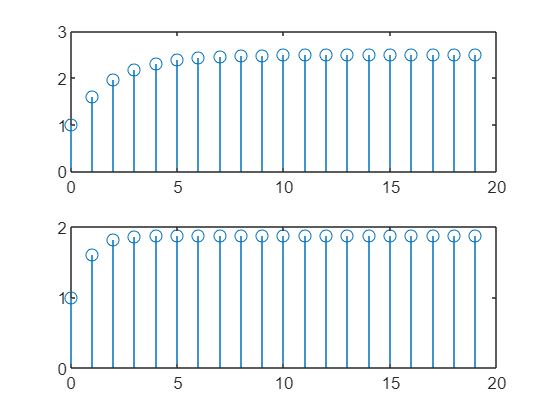

figure
subplot(2,1,1),stem(xn,z1)
subplot(2,1,2),stem(xn,z2)

**结论：**如答图。

(g)

题目要求：

**分析：**

% 绘制图像
figure
subplot(2,1,1),stem(xn,s1)
hold on
subplot(2,1,1),stem(xn,z1)
hold off

系统1是线性时不变系统，因此有s1[n] = u[n] * h1[n] = z1[n];

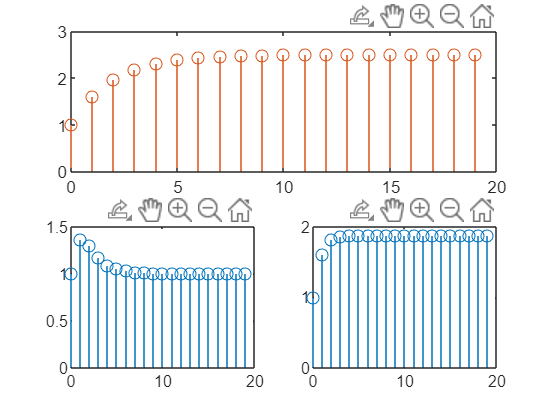

subplot(2,2,3),stem(xn,s2)
subplot(2,2,4),stem(xn,z2)

系统2不是线性时不变系统，没有这一性质，两者不相同。

**结论：**

若一系统为LTI系统，则该系统具有性质：s[n] = h[n] * u[n].